% The code might take several minutes to complete the bootstrap 
% (if you reduce the number of simulations to 100 it will run much faster)


% import of all datas 
datas=readtable('data_ps3.xlsx','Sheet',2);
head(datas)

       Var1        Var2      Var3     Var4       Var5                                       Var6                                
    __________    ______    ______    ____    __________    ____________________________________________________________________

    {'1960Q2'}    38.259    64.418    NaN     {'Y/L:'  }    {'Nonfarm Business Sector: Output Per Hour of All Persons (OPHNFB)'}
    {'1960Q3'}    38.333    64.241    NaN     {'HOURS' }    {'Hours per capita'                                                }
    {'1960Q4'}    37.854    63.572    NaN     {0×0 char}    {0×0 char                                                          }
    {'1961Q1'}    38.311    63.117    NaN     {0×0 char}    {0×0 char                                                          }
    {'1961Q2'}    39.

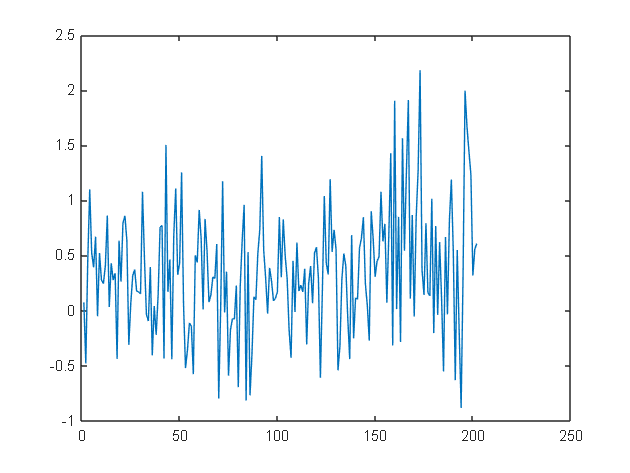


%parameters
numVars=2;
numLags=4;
impulse_horizion=20;
%setting the datas
prod_table=datas(:,"Var2");
hours_table=datas(:,"Var3");
prod=table2array(prod_table);
hours=table2array(hours_table);



% differenciation 
prod=diff(prod);
hours=diff(hours);

plot(prod)

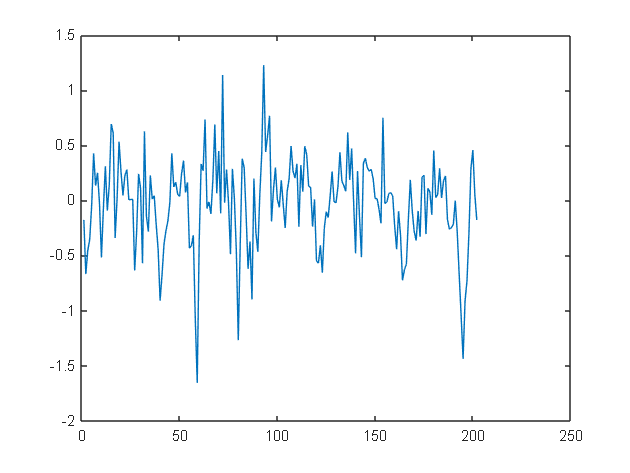

plot(hours)



data=[prod hours];




% Estimate the VAR
Mdl = varm(2,numLags);
EstMdl = estimate(Mdl, data);

% Step 2: Get the reduced-form residuals and covariance matrix
residuals = infer(EstMdl, data);
cov_resid = cov(residuals);  % Covariance matrix of the reduced-form residuals

% Step 3: Cholesky decomposition as an initial guess for the structural matrix A
A_chol = chol(cov_resid, 'lower');  % Initial decomposition (lower triangular matrix)

% Step 4: Calculate the long-run impact matrix for a VAR(4)
% Get the coefficient matrices from the VAR model
C1 = EstMdl.AR{1};  % Coefficient matrix for lag 1
C2 = EstMdl.AR{2};  % Coefficient matrix for lag 2
C3 = EstMdl.AR{3};  % Coefficient matrix for lag 3
C4 = EstMdl.AR{4};  % Coefficient matrix for lag 4



% Companion matrix
comp_mat = [C1 C2 C3 C4;
           eye(2) zeros(2,6);
           zeros(2,2) eye(2) zeros(2,4);
           zeros(2,4) eye(2) zeros(2,2)];

% VMA 
n_periods = 20; 
MA_coef = zeros(2,2,n_periods);
temp = eye(8);
MA_coef(:,:,1) = eye(2);

for i = 2:n_periods
    temp = temp * comp_mat;
    MA_coef(:,:,i) = temp(1:2,1:2);
end

%calculate the long-run matrix of the reduced form
C_inf = eye(2);
temp = eye(8);
for i = 1:1000  
    temp = temp * comp_mat;
    C_inf = C_inf + temp(1:2,1:2);
end

%Blanchard-Quah identification
G = chol(C_inf * cov_resid * C_inf')';  % Triangolare inferiore

% A0_inv
A0_inv = inv(C_inf) * G;

% SVMA calculation 
SVMA_coef = zeros(2,2,n_periods);
for i = 1:n_periods
    SVMA_coef(:,:,i) = MA_coef(:,:,i) * A0_inv;
end

% Check the matrix of long term effects
C_inf_struct = C_inf * A0_inv;  
disp("long run matrix")

long run matrix


disp(C_inf_struct)

    0.6066         0
   -0.1139    0.6368



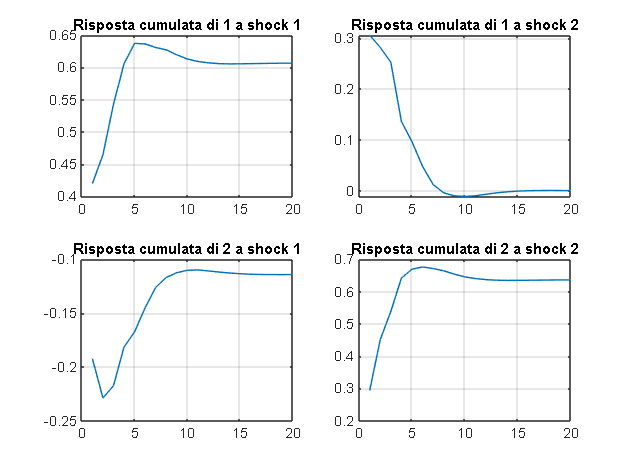




% IRF
SVMA_coef_cum = zeros(2,2,n_periods);
for i = 1:2
    for j = 1:2
        SVMA_coef_cum(i,j,:) = cumsum(squeeze(SVMA_coef(i,j,:)));
    end
end


figure
for i = 1:2
    for j = 1:2
        subplot(2,2,(i-1)*2+j)
        plot(squeeze(SVMA_coef_cum(i,j,:)))
        title(['Risposta cumulata di ' num2str(i) ' a shock ' num2str(j)])
        grid on
       
    end
end

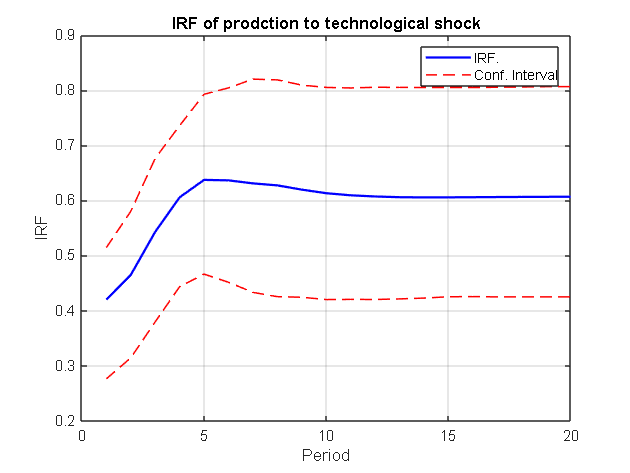


% Bootstrap 
n_boot = 1000; 
conf_level = 0.95; % confidence level
lower_bound = (1 - conf_level) / 2;
upper_bound = 1 - lower_bound;

SVMA_boot = zeros(2, 2, impulse_horizion, n_boot);
SVMA_boot_cum = zeros(2, 2, impulse_horizion, n_boot); % IRF cumulate bootstrap

% Starting bootstrap process
rng(123); 
for b = 1:n_boot
    % Resampling 
    boot_residuals = residuals(randi(size(residuals, 1), size(residuals, 1), 1), :);
    
    boot_data = zeros(size(data));
    boot_data(1:numLags, :) = data(1:numLags, :);
    for t = (numLags+1):size(data, 1)
        
        forecast = zeros(1, 2);
        for lag = 1:numLags
            forecast = forecast + boot_data(t-lag, :) * EstMdl.AR{lag}';
        end
        % Adding residuals 
        boot_data(t, :) = forecast + boot_residuals(t - numLags, :);
    end
    
    % Re-estimate VAR
    Mdl_boot = varm(2, numLags);
    EstMdl_boot = estimate(Mdl_boot, boot_data);
    
    
    residuals_boot = infer(EstMdl_boot, boot_data);
    cov_resid_boot = cov(residuals_boot);
    
    % Calculate companion matrix for bootstrap model
    C_boot = EstMdl_boot.AR;
    comp_mat_boot = [C_boot{1} C_boot{2} C_boot{3} C_boot{4};
                     eye(2) zeros(2,6);
                     zeros(2,2) eye(2) zeros(2,4);
                     zeros(2,4) eye(2) zeros(2,2)];
    % Compute MA coefficients for bootstrap sample            
    MA_boot = zeros(2, 2, impulse_horizion);
    temp_boot = eye(8);
    MA_boot(:,:,1) = eye(2);
    for i = 2:impulse_horizion
        temp_boot = temp_boot * comp_mat_boot;
        MA_boot(:,:,i) = temp_boot(1:2, 1:2);
    end
    
    % Compute long-run matrices and structural impact for bootstrap
    C_inf_boot = eye(2);
    temp_boot = eye(8);
    for i = 1:1000
        temp_boot = temp_boot * comp_mat_boot;
        C_inf_boot = C_inf_boot + temp_boot(1:2, 1:2);
    end
    G_boot = chol(C_inf_boot * cov_resid_boot * C_inf_boot')';
    A0_inv_boot = inv(C_inf_boot) * G_boot;
    
   % Compute bootstrap SVMA coefficients
    for i = 1:impulse_horizion
        SVMA_boot(:,:,i,b) = MA_boot(:,:,i) * A0_inv_boot;
    end
    
    % Compute cumulative bootstrap IRFs
    for i = 1:2
        for j = 1:2
            SVMA_boot_cum(i,j,:,b) = cumsum(squeeze(SVMA_boot(i,j,:,b)));
        end
    end
end

% Compute confidence intervals for cumulative IRFs
SVMA_low_cum = zeros(2, 2, impulse_horizion);
SVMA_high_cum = zeros(2, 2, impulse_horizion);

for i = 1:2
    for j = 1:2
        for h = 1:impulse_horizion
            irf_cum_dist = squeeze(SVMA_boot_cum(i, j, h, :));
            SVMA_low_cum(i, j, h) = quantile(irf_cum_dist, lower_bound);
            SVMA_high_cum(i, j, h) = quantile(irf_cum_dist, upper_bound);
        end
    end
end

% Plot cumulative IRFs with confidence intervals
SVMA_coef_cum = zeros(2, 2, impulse_horizion);
for i = 1:2
    for j = 1:2
        SVMA_coef_cum(i,j,:) = cumsum(squeeze(SVMA_coef(i,j,:)));
    end
end

% IRF Cumulate prodction to technological shock
figure;
plot(1:impulse_horizion, squeeze(SVMA_coef_cum(1,1,:)), 'b', 'LineWidth', 1.5); hold on;
plot(1:impulse_horizion, squeeze(SVMA_low_cum(1,1,:)), 'r--', 'LineWidth', 1);
plot(1:impulse_horizion, squeeze(SVMA_high_cum(1,1,:)), 'r--', 'LineWidth', 1);
title('IRF of prodction to technological shock');
xlabel('Period');
ylabel('IRF');
grid on;
legend('IRF.', 'Conf. Interval');
hold off;

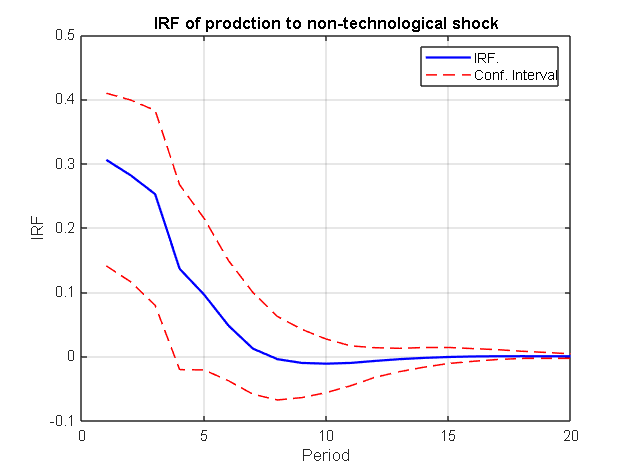


% IRF of prodction to non-technological shock
figure;
plot(1:impulse_horizion, squeeze(SVMA_coef_cum(1,2,:)), 'b', 'LineWidth', 1.5); hold on;
plot(1:impulse_horizion, squeeze(SVMA_low_cum(1,2,:)), 'r--', 'LineWidth', 1);
plot(1:impulse_horizion, squeeze(SVMA_high_cum(1,2,:)), 'r--', 'LineWidth', 1);
title('IRF of prodction to non-technological shock');
xlabel('Period');
ylabel('IRF');
grid on;
legend('IRF.', 'Conf. Interval');
hold off;

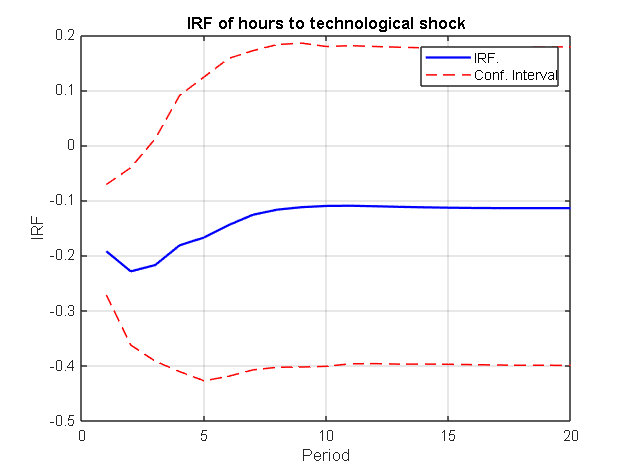


% IRF hours to technological shock
figure;
plot(1:impulse_horizion, squeeze(SVMA_coef_cum(2,1,:)), 'b', 'LineWidth', 1.5); hold on;
plot(1:impulse_horizion, squeeze(SVMA_low_cum(2,1,:)), 'r--', 'LineWidth', 1);
plot(1:impulse_horizion, squeeze(SVMA_high_cum(2,1,:)), 'r--', 'LineWidth', 1);
title('IRF of hours to technological shock');
xlabel('Period');
ylabel('IRF');
grid on;
legend('IRF.', 'Conf. Interval');
hold off;

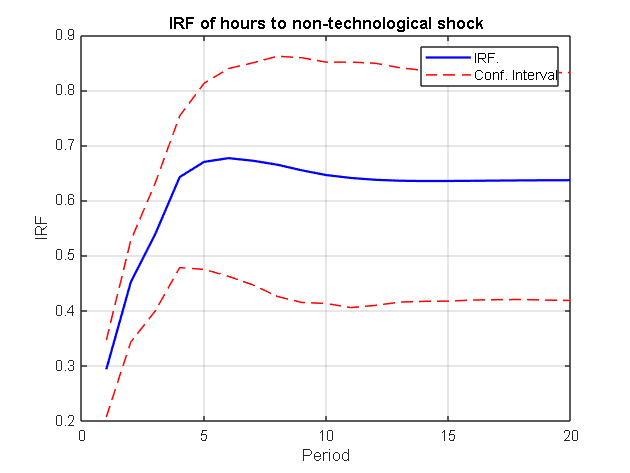


% IRF hours to non-technological shock
figure;
plot(1:impulse_horizion, squeeze(SVMA_coef_cum(2,2,:)), 'b', 'LineWidth', 1.5); hold on;
plot(1:impulse_horizion, squeeze(SVMA_low_cum(2,2,:)), 'r--', 'LineWidth', 1);
plot(1:impulse_horizion, squeeze(SVMA_high_cum(2,2,:)), 'r--', 'LineWidth', 1);
title('IRF of hours to non-technological shock');
xlabel('Period');
ylabel('IRF');
grid on;
legend('IRF.', 'Conf. Interval');
hold off;

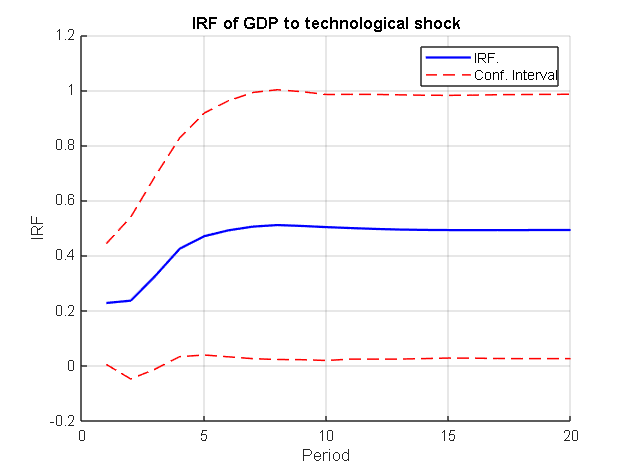


% Sum of the cumulate IRF (Prod+hours) to get GDP
GDP_IRF_cum = squeeze(SVMA_coef_cum(1, :, :) + SVMA_coef_cum(2, :, :));
GDP_IRF_low_cum = squeeze(SVMA_low_cum(1, :, :) + SVMA_low_cum(2, :, :));
GDP_IRF_high_cum = squeeze(SVMA_high_cum(1, :, :) + SVMA_high_cum(2, :, :));

% IRF of GDP to technological shock
figure;
hold on;
plot(1:impulse_horizion, GDP_IRF_cum(1, :), 'b', 'LineWidth', 1.5); % IRF cumulata
plot(1:impulse_horizion, GDP_IRF_low_cum(1, :), 'r--', 'LineWidth', 1); % Limite inferiore
plot(1:impulse_horizion, GDP_IRF_high_cum(1, :), 'r--', 'LineWidth', 1); % Limite superiore
title('IRF of GDP to technological shock');
xlabel('Period');
ylabel('IRF');
grid on;
legend('IRF.', 'Conf. Interval');
hold off;

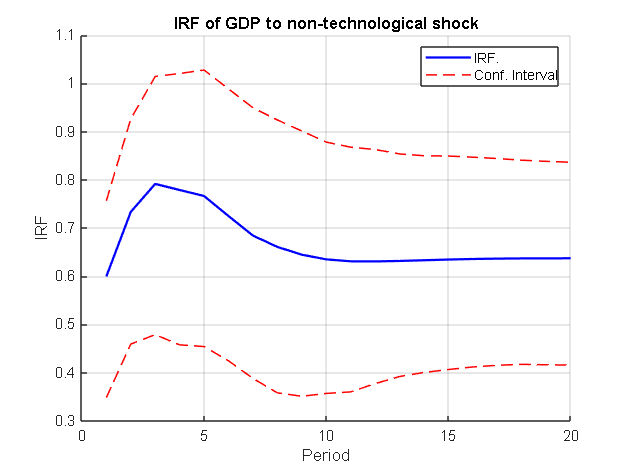


% IRF of GDP to non-technological shock
figure;
hold on;
plot(1:impulse_horizion, GDP_IRF_cum(2, :), 'b', 'LineWidth', 1.5); % IRF cumulata
plot(1:impulse_horizion, GDP_IRF_low_cum(2, :), 'r--', 'LineWidth', 1); % Limite inferiore
plot(1:impulse_horizion, GDP_IRF_high_cum(2, :), 'r--', 'LineWidth', 1); % Limite superiore
title('IRF of GDP to non-technological shock');
xlabel('Period');
ylabel('IRF');
grid on;
legend('IRF.', 'Conf. Interval');
hold off;